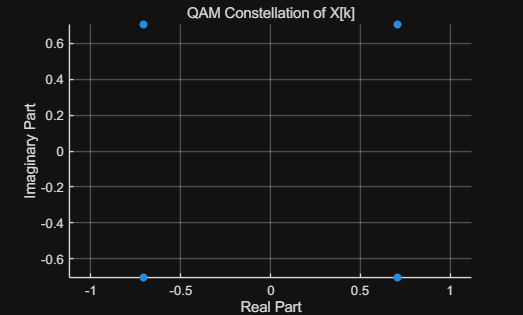

% This script demonstrates the relationship Y[k] = X[k]·H[k] + Z[k] in OFDM systems
% using proper QAM modulation

% System Parameters
N = 64;                     % FFT size / Number of subcarriers
SNR_dB = 20;               % Signal-to-Noise Ratio in dB
M = 4;                     % M-QAM modulation order (4 for QPSK)

% Generate random data bits and map to QAM symbols
data_bits = randi([0 M-1], N, 1);           % Random integers between 0 and M-1
X = qammod(data_bits, M, 'UnitAveragePower', true);  % Proper QAM modulation

% Generate channel impulse response (h[n])
h = [1; 0.5; 0.2];         % Three-tap channel impulse response
H = fft(h, N);             % Channel frequency response (H[k])

% Convert X[k] to time domain
x = ifft(X);               % x[n] = IDFT{X[k]}

% Apply channel in time domain (convolution)
y_without_noise = conv(x, h);
y_without_noise = y_without_noise(1:N);  % Take first N samples

% Generate and add noise
signal_power = mean(abs(y_without_noise).^2);
noise_power = signal_power / (10^(SNR_dB/10));
z = sqrt(noise_power/2) * (randn(N,1) + 1j*randn(N,1));
y = y_without_noise + z;

% Convert to frequency domain
Y = fft(y);                % Y[k] = DFT{y[n]}
Z = fft(z);                % Z[k] = DFT{z[n]}

% Verify the relationship Y[k] = X[k]·H[k] + Z[k]
Y_calculated = X.*H + Z;   % Direct calculation using the relationship
Y_difference = abs(Y - Y_calculated);  % Should be very small due to numerical precision

% Plot results
figure('Position', [100 100 1200 800]);

% Plot 1: QAM Constellation of X[k]
figure;
scatter(real(X), imag(X), 'filled');
title('QAM Constellation of X[k]');
xlabel('Real Part');
ylabel('Imaginary Part');
grid on;
axis equal;

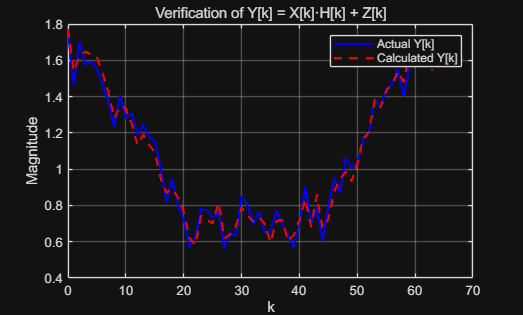



% Plot 3: Verification of Relationship
figure;
plot(0:N-1, abs(Y), 'b-', 'LineWidth', 1.5);
hold on;
plot(0:N-1, abs(Y_calculated), 'r--', 'LineWidth', 1.5);
title('Verification of Y[k] = X[k]·H[k] + Z[k]');
xlabel('k');
ylabel('Magnitude');
legend('Actual Y[k]', 'Calculated Y[k]');
grid on;

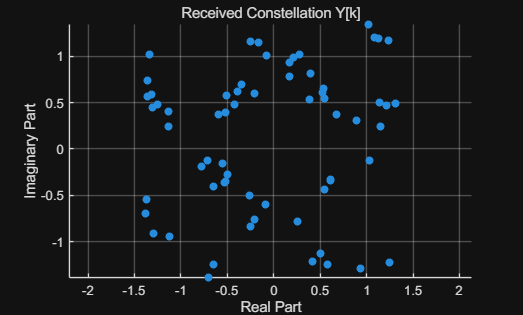


% Plot 4: Received Constellation
figure;
scatter(real(Y), imag(Y), 'filled');
title('Received Constellation Y[k]');
xlabel('Real Part');
ylabel('Imaginary Part');
grid on;
axis equal;


% Print maximum error
fprintf('Maximum difference between Y[k] and X[k]·H[k] + Z[k]: %.2e\n', max(Y_difference));

Maximum difference between Y[k] and X[k]·H[k] + Z[k]: 8.00e-02
